# First harmonic

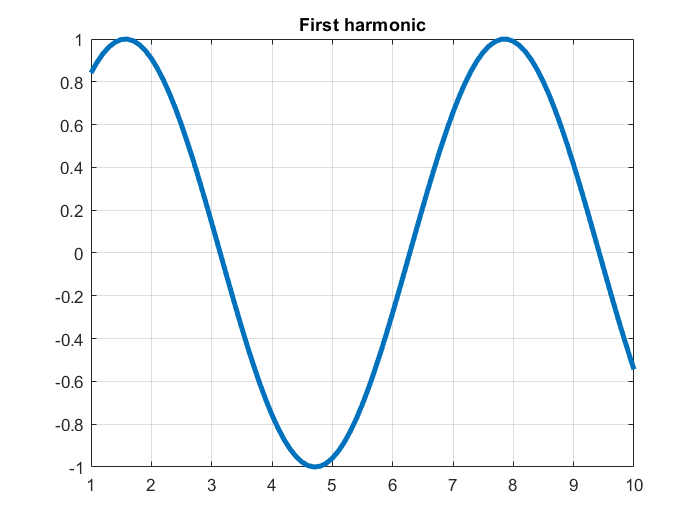

% Creating time vector 't':
t = 1: 0.1 :10;

% Generating a sinusoidal signal from the 't':
y = sin(t);

% Creating and setting up plot:
plot(t,y,'LineWidth',3); 
grid on;
title ('First harmonic');

## Adding third harmonic

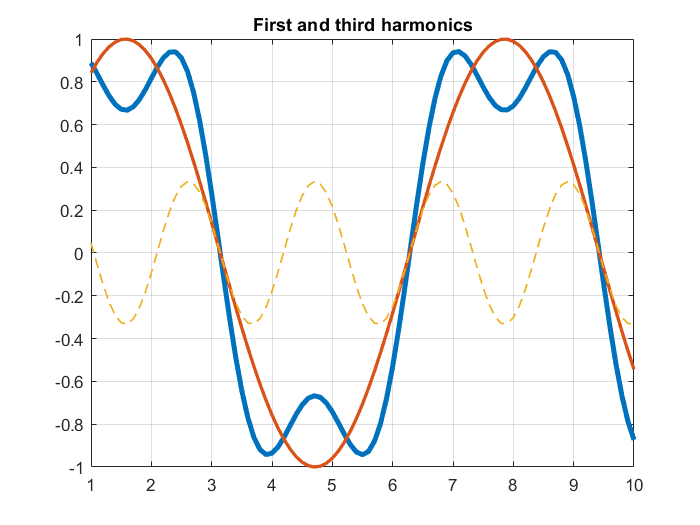

% Generating a signal with third harmonic from sinusoidal signal 'y' by adding
% a higher frequency of three times and correspondingly lower amplitude:
y3 = sin(t) + sin(3*t)/3;

% Creating and setting up plot:
plot(t,y3,'LineWidth',3); 
grid on;
hold on;
title ('First and third harmonics');

% Adding 'y' and 'y3' for comparison:
plot (t,y,'LineWidth',2,'LineStyle','-')
plot(t,sin(3*t)/3,'LineWidth',1,'LineStyle','--'); 
hold off;

## Adding 5,7 and 9 harmonics

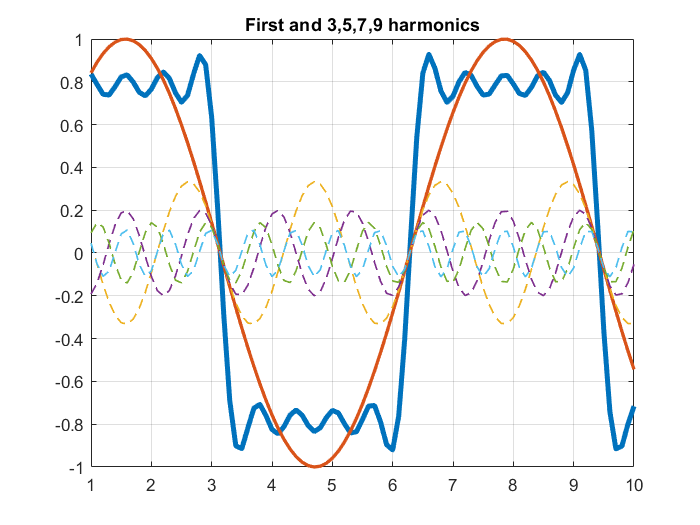

% Generating a signal with third harmonic from sinusoidal signal 'y' by adding
% a higher frequency of 5,7 and 9 times and correspondingly lower amplitude:
y5 = sin(t) + sin(5*t)/5;
y7 = sin(t) + sin(7*t)/7;
y9 = sin(t) + sin(9*t)/9;

% Creat S - summ of harmonics:
S = sin(t) + sin(3*t)/3 + sin(5*t)/5 + sin(7*t)/7 + sin(9*t)/9;

% Creating and setting up plot:
plot(t,S,'LineWidth',3); 
grid on;
hold on;
title ('First and 3,5,7,9 harmonics');

% Adding 'y' and 'y3','y5','y7','y9' for comparison:
plot (t,y,'LineWidth',2,'LineStyle','-')
plot(t,sin(3*t)/3,t,sin(5*t)/5,t,sin(7*t)/7,t,sin(9*t)/9,'LineWidth',1,'LineStyle','--'); 
hold off;

## Fft

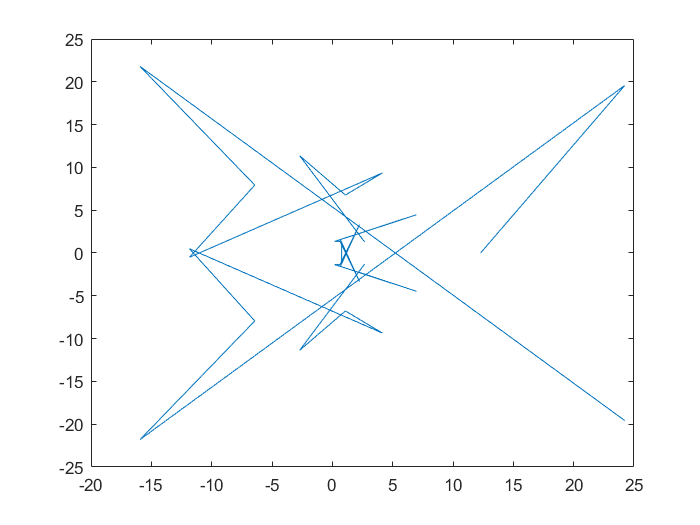

% Fast Fourier transform and an attempt to visualize the spectrum:
FrS=fft(S);
plot(FrS);

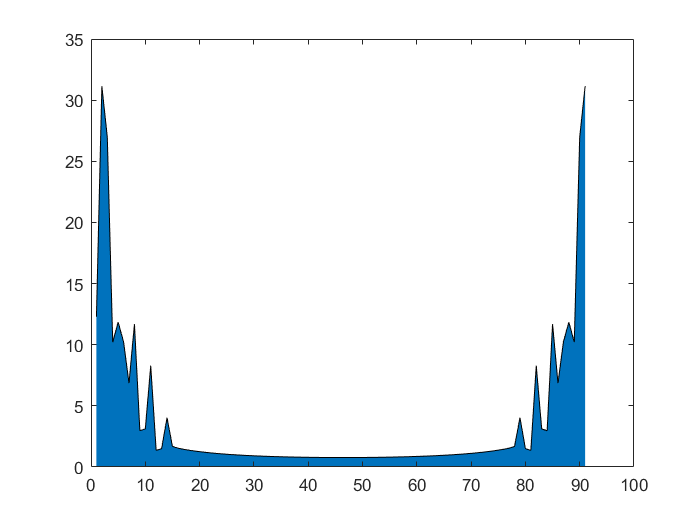

% Building the amplitude spectrum of the signal:
area(abs(FrS));

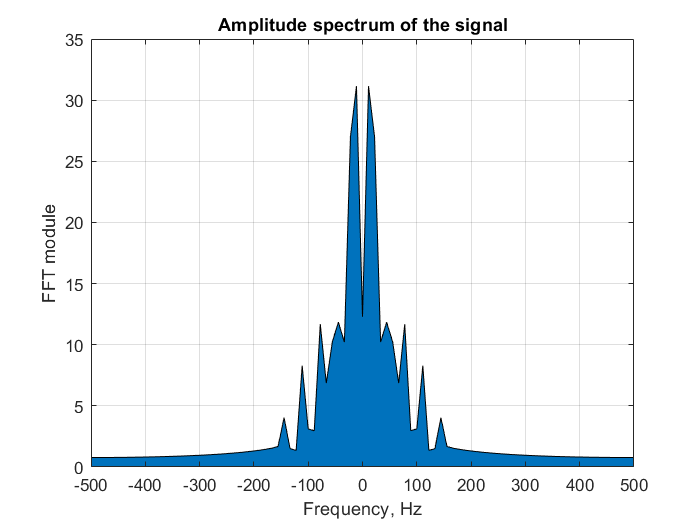

% The fftshift function transforms the spectrum (the output 
% of the fft function) and shifts the readings symmetrically
% about the zero frequency:
FrSshift = fftshift(FrS);
F = linspace(-(1/0.001)/2,(1/0.001)/2,length(FrS));
area(F,abs(FrSshift));
xlim([-500 500]);
grid on; 
title('Amplitude spectrum of the signal');
xlabel('Frequency, Hz');
ylabel('FFT module');

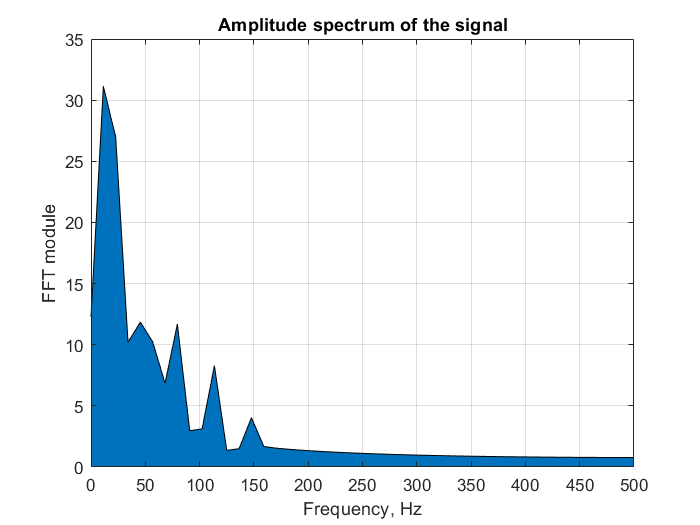

% Spectrum in the region of positive frequencies:
Xpositive = FrS([1:length(FrS)/2]);
FrSpositive = linspace(0,(1/0.001)/2,length(Xpositive));
area(FrSpositive,abs(Xpositive));
xlim([0 500]);
grid on;
hold on;
title('Amplitude spectrum of the signal');
xlabel('Frequency, Hz');
ylabel('FFT module');

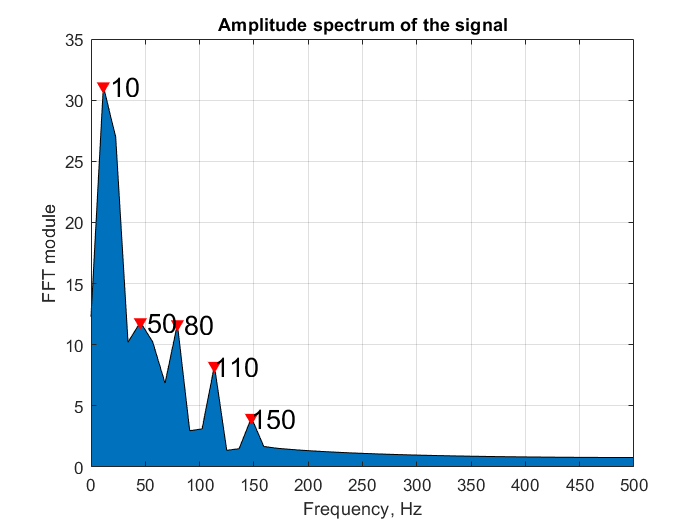

% Finding the maxima of the real part of the spectrum:
[~,locs] = findpeaks(abs(Xpositive),'MinPeakHeight',1,...
                                    'MinPeakDistance',1);
Fpeaks = FrSpositive(locs);                              
plot(Fpeaks,abs(Xpositive(locs)),'rv','MarkerFaceColor','r');
cellpeaks = cellstr(num2str(round(Fpeaks',-1)));
text(Fpeaks,abs(Xpositive(locs)),cellpeaks,'FontSize',16);
hold off;